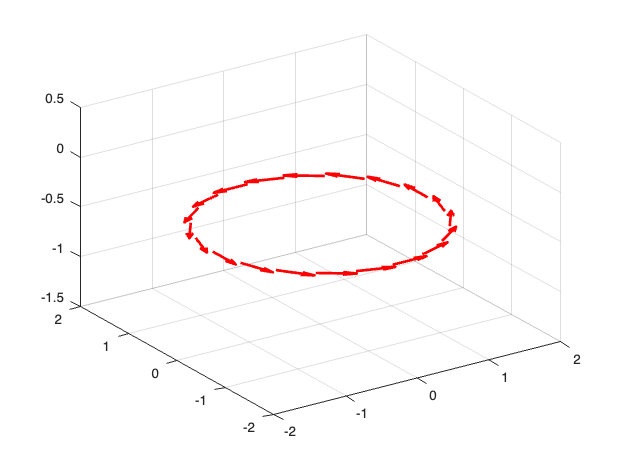

%Code starts here
%Complete the code in the left, using the comments in the right.
%-----------------------------------------------------------------------
clc;         % Limpia el area de trabajo             
clear vars ; % Limpia la ventana de comandos
close all;   % Limpia los elementos de las figuras
nl = 1;      % La variable "nl" representa el
% número de loops que tendrá la simulación.
% Un loop sería simplemente una espira
% Mas de un loop seria una bobina
ds = 0.1;    %La variable "ds" representa el
% diferencial de longitud.
x = -5:ds:5;           
y = -5:ds:5;           
z = x;
% Definimos los vectores, x, y, z iguales para que nuestro
% area de trabajo sea de -5 a 5 en pasos de 0.1.
%Se va a crear un vector 1x101 array doble
Lx = length(x);        
Ly = length(y);        
Lz = length(z);      
%Utilizamos la funcion lenght para obtener la longitud del
% array en x, y, z.
rw = 0.2; % Esta variable es la longitud del cable
I = 300;%Esta variable es la corriente en A
mo=4*pi*1e-7; % Esta es la permeabilidad del vacio y tiene unidades
% H/m
km=mo*I/(4*pi); % Formula para caulcular el campo magnetico
% que es constante y sus unidades son T
N = 20;  % N es el numero de puntos por espira
R = 1.5; %R es el radio de la espira
sz=1; %sz representa el step zise del loop en el eje z
s=1; % S representa el contador inicial
% para indexar puntos de cada espira.
dtheta = 2 * pi / N; %Aqui definimos el diferencial del
% angulo con respecto al centr. Como tenemos 20 puntos en la
% espira para obtener ese diferencial dividimos 2pi (radianes)
% entre ese numero de puntos
dl = R * dtheta; %Definimos el diferencial de "dl"
% multiplicando el radio por dtheta EZ
ang = 0:dtheta:(2*pi - dtheta);  % Se define un vector
% llamado angulo de 0 a 2pi con un paso de dtheta
% Va desde 0 a 2pi-dtheta porque 0 y 2pi son el mismo
% punto.

% Posiciones x
Px = zeros(1, N*nl);
Py = zeros(1, N*nl);
Pz = zeros(1, N*nl);
% Componentes x,y,z de la flecha
dx = zeros(1, N*nl);
dy = zeros(1, N*nl);
dz = zeros(1, N*nl);

for I = 1:nl    % Ciclo for que va desde 1 a nl que nos va a dar un bucle por espira
                           
   Px(s:s+N-1) = R * cos(ang);%Coordenada x de cada punto
   Py(s:s+N-1) = R * sin(ang);%Mismo que el anterior pero en y por ende usamos sen
   Pz(s:s+N-1) = -nl/2*sz + (I-1)*sz; %Coordenada z fija para la espira i, distribuida centrada
                              

   dx(s:s+N-1) = -Py(s:s+N-1) * dtheta; %Componente x del vector diferencial de corriente
   dy(s:s+N-1) = Px(s:s+N-1) * dtheta;  % Mismo que el anterior pero en y

    s = s + N;              % Se avanza el índice para el siguiente punto de la espira

end

dz(1:N*nl) = 0;%No hay componente de corriente en z, ya que las espiras son planas.
figure(1)




%Visualización con quiver3:
quiver3(Px, Py, Pz, dx, dy, dz, 0.5, '-r', 'LineWidth', 2)

%quiver3 dibuja flechas en 3D.
%(Px,Py,Pz): posición base de cada flecha
%(dx,dy,dz): dirección y magnitud de cada flecha
%0.5: factor de escala para el tamaño de las flechas
%'-r': color rojo
%'LineWidth', 2: grosor de las flechas

view(-34, 33)%Ajustamos la vista en 3D para un mejor ángulo visual

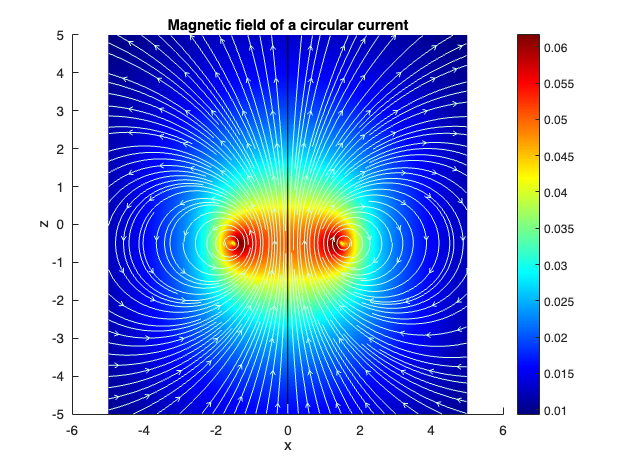

ans = 5

ans = 4.9881

ans = 4.9643

ans = 4.9285

ans = 4.8809

ans = 4.8213

ans = 4.7500

ans = 4.6667

ans = 4.5717

ans = 4.4648

ans = 4.3462

ans = 4.2159

ans = 4.0740

ans = 3.9205

ans = 3.7556

ans = 3.5793

ans = 3.3918

ans = 3.1934

ans = 2.9843

ans = 2.7649

ans = 2.5356

ans = 2.2970

ans = 2.0502

ans = 1.7963

ans = 1.5370

ans = 1.2744

ans = 1.0112

ans = 0.7496

ans = 0.4909

ans = 0.2334

ans = -0.0287

ans = -0.3040

ans = -0.6013

ans = -0.9254

ans = -1.2764

ans = -1.6511

ans = -2.0462

ans = -2.4587

ans = -2.8867

ans = -3.3292

ans = -3.7853

ans = -4.2546

ans = -4.7367



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Magnetic-field Calculation & Visualization %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Array 3x3
dBx = zeros(Lx, Ly, Lz);% Componente X del campo magnético inicializado en ceros
dBy = zeros(Lx, Ly, Lz);% Mismo que el anterior pero para y
dBz = zeros(Lx, Ly, Lz);% Mismo que el anterior pero para z


for I = 1:Lx                    %Un loop que va desde 1 a Lx 
   for J = 1:Ly                 %Mismo para y
       for K = 1:Lz             %Igualmente pero para z
           for L= 1:(nl*N)      %Otro for que va desde 1 a
                                %el numero de loops multiplicado puntos por loop,
                                %por si tuvieramos mas de un loop


               rx = x(I) - Px(L);   %Componente r en x
               ry = y(J) - Py(L);   %Mismo en y
               rz = z(K) - Pz(L);   %Mismo en z

               r = sqrt(rx^2 + ry^2 + rz^2+rw^2);      %Esta es la magnitud de r
               r3 = r^3;                               %Declaramos una variable r3 igual a la magnitud de r elevado al cubo


               dBx (I,J,K) = dBx(I, J, K) + km * dy(L) * rz / r3; %Definimos el diferencial del campo en x
               dBy (I,J,K) = dBy(I, J, K) + km * dx(L) * rz / r3; %Mismo que el pasado pero en y

               dBz (I,J,K) = dBz(I, J, K) + km * (dx(L) *ry - dy(L) * rx) / r3;   %Mismo que los pasados pero en z

                                             
              
            end   %Close the 4th loop

        end    %Close the 3rd loop   
    end   %Close the 2nd loop
end    %Close the 1st loop


%------------------------------------------------------------
%Uncomment all the following, and explain (comment) each line
%------------------------------------------------------------

Bmag=sqrt(dBx.^2+dBy.^2+dBz.^2);    %Magnitud del Campo magnetico
centery=round(Ly/2);             % Round redondea la longitud de y entre 2
Bx_xz=squeeze(dBx(:,centery,:));    % Extrae la componente Bx del campo magnético en el plano XZ (fijando Y = centery)
Bz_xz = squeeze(dBz(:,centery,:));      % Extrae la componente Bz del campo magnético en el plano XZ (fijando Y = centery)
Bxz   = squeeze(Bmag(:,centery,:));     % Extrae la magnitud total del campo magnético en el plano XZ

figure(2)                           %Muestra la figura del campo
hold on
pcolor(x,z,(Bxz').^(1/3)); shading interp; colormap jet; colorbar   
% Muestra un mapa de color de la magnitud del campo magnético en el plano XZ
% Se eleva a la 1/3 para visualizar mejor valores bajos y altos
% 'shading interp' suaviza la interpolación entre colores
% 'colormap jet' aplica un degradado de colores tipo "arcoíris"
% 'colorbar' muestra la escala de colores a la derecha

h1=streamslice(x,z,Bx_xz',Bz_xz',3); % Dibuja líneas de
% flujo del campo usando las componentes Bx y Bz en el plano XZ
% El 3 controla la densidad de las líneas de flujo
%(entre más alto, menos densas)    

set(h1, 'Color', [0.8 1 0.9]);          %Cambia el color de las líneas de flujo a un tono verde claro
xlabel('x')                              % Etiqueta del eje X
ylabel ('z')                             % Etiqueta del eje Z
title('Magnetic field of a circular current')  %Título de la gráfica
zz(length(ang))=0;



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%           Session 3 | Step 1              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Rodrigo Gamboa & Francisco Montes | May 2024


%-OBJECTIVE-%

%In this activity you will learn to calculate the force between two sources of magnetic field.
%Specifically, you will calculate the force that a falling magnet (magnetic dipole) will experiment, 
%due to its interaction your former circular coil in the ground (with current I). 
%You will use and extend your code from the previous session.

%Recall commenting and completing all necessary code from now on,
%as this will impact the quality and grade of the associate Deliverable.


%-----------------------------------------------------------------------
%Code starts here (paste this work below your previous code viceversa)
%Complete the code in the left, using the comments in the right.
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------%%
%-----------------------------------------------------------------------%%
%-------------------------Dipole Falling Part---------------------------%%
%-----------------------------------------------------------------------%%
%-----------------------------------------------------------------------%%

%Reseach and explain (in your own words), what is magnetic moment in general, 
%and for a permanent magnet (simple equations are allowed and expected):
% The magnetic moment shows how strong and which way a magnet or current loop creates a magnetic field.
% For a current loop: magnetic moment = current × area of the loop.
% For a permanent magnet, it depends on how its atoms are aligned.
% A bigger magnetic moment means the magnet interacts more strongly with magnetic fields.



%New code starts here!

mag= 2000;        %(Magnetic moment of the magnet)
                  %Intensidad y orientacion del "Dipolo Magentico
                  %and initialize to 2000. What are its units? "A*m^2"


mag_mass= 0.004;    %Declare the Magnet´s mass in kg, use 0.004 to begin.
                    %How many grams is this= 0.004kg---> 4 gr?

g= 9.81;            %Gravedad

w = mag_mass*g;     %Magnet´s weigth in N ---> Masa x gravedad = peso

zo = 5;             %Magnet's initial position


dt = 0.05;          %time step 


zm(1) = zo;         %(magnet position) and store in its first value the Magnet's initial position
                    %Cuando hay Fuerzas MAGNÉTICAS actuando


zmfree(1) = zo;    %"zmfree", which stands for the magnte free fall case
                   %think we introduced this --> Guardar las posiciones de caida libre
                   %cuando no hay fuerzas actuando aparte de la gravedad


tt(1) = 0;         %Declare a vector called "tt" (time) vector de tiempo


vz(1) = 0;         %Declare a vector called "vz" (Z component for velocity)


vzfree(1) = 0;     % "vzfree". Again, why? -> Obtener la velocidades de mi magneto en caso de caida libre sin fuerzas
                   % aparte de la gravedad


cc = 1;            %cc=1 --> Contador del ciclo


h=animatedline;        %Use the animatedline function (use Matlab´s upper-right search function bar) to create an
                       %animated line that has no data and adds it to the current axes. Later (a few lines below),
                       %add points to the line in a loop using the addpoints function, add data.


%<start  while>          %Start a while loop running until the position of the magnet (dinamically) in z
while zm(cc) > -5
     zm(cc)              %For diagnostics purposes, print the position of the magnet in z. 

     addpoints(h, 0, zm(cc));   %Using the addpoints function mentioned above, add points (the zm(cc) ones) 
                                           %to the path, centered in x=0.
    
    
    drawnow                                 %Use drawnow to update and/or modify graphics objects 
    
    head = scatter(0, zm(cc), 100, 'filled');   % Visualiza la posición actual del imán en la animación colocando 
                                            % un punto grande y relleno en (x=0, z=zm(cc))
   
    %%%%%%%%%%%%%%%%%
    %<NEW STUFF HERE>
    %%%%%%%%%%%%%%%%%

    %Go to the Canvas tab called "Stage 2: Magnetic Force between two magnetic
    %dipoles", read through it and perform the referred calculations. Using
    %this result. Get the force experienced by the Magnet Fm(cc), as a function
    %of z, i.e., as a function of it´s height. Use (adapt) your results to the 
    %variable names in yout code.


    Fm(cc) = -mag * (mo * I * R^2 * (-3) * zm(cc)) / (2 * (zm(cc)^2 + R^2)^(5/2)); % Calcula la fuerza magnética que actúa 
                                                                                    % sobre el imán en su posición actual

    F(cc) = -w + Fm(cc);                     %Net (total) force over the
                                             %magnet F(cc). Important, it 
                                             %is net force.
                                                                 
                                                                    

    a = F(cc) / mag_mass;       %Using the total force get the instantaneous acceleration and label it as "a".
    pause(0.01);                %Use the pause function, with a value of 0.01, to grasp the
                                %head´s magnet movement.



    zm(cc+1) = zm(cc) + vz(cc)*dt + 0.5*a*dt^2;        %Get new magnet´s position z(cc+1) using high school physics, 
                                                       % Actualiza la posicion del iman usando la 
                                                       % formula de cinematica con aceleración constante

    zmfree(cc+1) = zmfree(cc) + vzfree(cc)*dt - 0.5*9.81*dt^2;     %Do the same but for the free fall case,
                                                                   %i.e., with no magnetic braking.

    vz(cc+1) = (zm(cc+1) - zm(cc)) / dt;          %Get new magnet´s approx. velocity using basic velocity definition over
                                                  %a time interval dt, i.e., vz(cc+1) = delta(z)/delta(t).
    
     

    vzfree(cc+1) = (zmfree(cc+1) - zmfree(cc)) / dt;    % Calcula la velocidad instantanea del iman 
                                                        % en caida libre usando la diferencia de posiciones
   

     cc = cc + 1;                    %Increase the cc counter in one unit.

   delete(head)                
                                
end %             Close the while loop

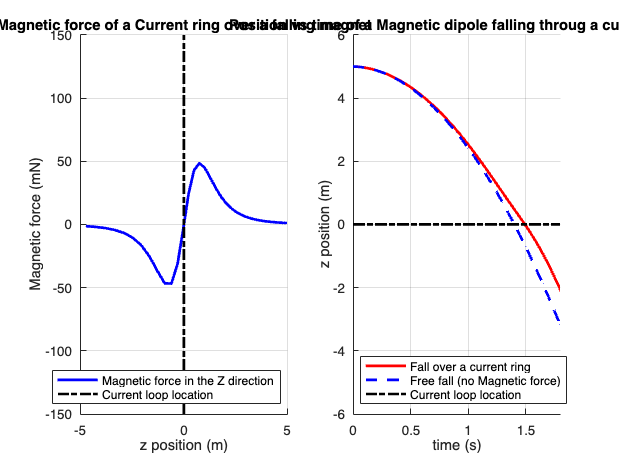


%---------------------------------------------------------------------
%--Final Part---------------------------------------------------------
%---------------------------------------------------------------------

%Uncomment all of the following, and explain in 
%detail (in next step of the code, not now) what it does or will do. 

figure(4)
subplot(1,2,1)

hold on
plot(zm(1:length(Fm)),1000*Fm, '-b', 'LineWidth', 2) %Why do we have 1000Fm? -> Transaforma
                                                    % Newtons a miliNewtons 1N=1000mN
plot([0,0],[-150,150],'-.k','LineWidth', 2)
grid on
xlabel 'z position (m)'
ylabel 'Magnetic force (mN)'
title 'Magnetic force of a Current ring over a falling magnet'
legend('Magnetic force in the Z direction','Current loop location','Location','southeast')

subplot(1,2,2)

hold on
tt=0:dt:(cc-1)*dt;
plot(tt,zm,'-r', 'LineWidth', 2)
plot(tt,zmfree,'--b', 'LineWidth', 2)   
plot([0,1.8],[0,0],'-.k','LineWidth', 2)
grid on
xlabel 'time (s)'
ylabel 'z position (m)'
title 'Position vs time of a Magnetic dipole falling throug a current ring'
legend('Fall over a current ring','Free fall (no Magnetic force)', 'Current loop location','Location','southwest')
axis([0 1.8 -6 6])

%---------------------------------------------------------------------
%--Final Part---------------------------------------------------------
%---------------------------------------------------------------------

figure(4)
subplot(1,2,1)

hold on
plot(zm(1:length(Fm)),1000*Fm, '-b', 'LineWidth', 2) %Why do we have 1000Fm?
plot([0,0],[-150,150],'-.k','LineWidth', 2)
grid on
xlabel 'z position (m)'
ylabel 'Magnetic force (mN)'
title 'Magnetic force of a Current ring over a falling magnet'
legend('Magnetic force in the Z direction','Current loop location','Location','southeast')

subplot(1,2,2)

hold on
tt=0:dt:(cc-1)*dt;
plot(tt,zm,'-r', 'LineWidth', 2)
plot(tt,zmfree,'--b', 'LineWidth', 2)   
plot([0,1.8],[0,0],'-.k','LineWidth', 2)
grid on
xlabel 'time (s)'
ylabel 'z position (m)'
title 'Position vs time of a Magnetic dipole falling throug a current ring'
legend('Fall over a current ring','Free fall (no Magnetic force)', 'Current loop location','Location','southwest')
axis([0 1.8 -6 6])



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%FINALLY: Run and test your code for limit cases!
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%<THIS IS PART OF YOUR DELIVERABLE NO.1>


%(1) What happens if the magnetic moment is zero? (run and explain).
% if the magnetic moment is zero the magnet falss only with the gravity
% force, just like a normal object in free fall.

%(2) What happens if the mass of the magnet is set to 1 kg? (run and explain).
% If the magnet’s mass is increased to 1 kg, the magnet will fall much
% faster,  because the heavier the magnet, the less effect the magnetic force has on stopping it.

%(3) What happens if you increase the actual value for the magnetic
% moment one order if magnitude? (run and explain).
% The magnet will be much more affected by the coil, so it will fall more
% slowly or depending wich value you define, is not going to fall, its
% going to be bouncing

%(4) What happens if you decrease the mass of the magnet by one 
% order of magnitude? (run and explain).
% The magnet becomes much lighter, the magnet will fall much slower, it
% takes a lot longer to reach the bottom, and again its going to be
% bouncing

%(5) How many plots are you getting at the end? Explain each in full
%detail. Full details please!
% We have two plots in the leff we have "Magnetic force of a Current ring over a falling magnet"
% this plot shows how the magnetic force acts on the falling magnet as it moves up and down along the z-axis.
% The blue curve shows how the force changes as the magnet falls. 
% and when the magnet is near the coil (z = 0), the magnetic force is strongest.
% and the force changes direction depending on where the magnet is.

% And in the right plot we have the "Position vs time of a Magnetic dipole falling through a current ring"
% this plot shows how the magnet’s position changes over time as it falls,
% in the horizonta axis we have time, and in the vertical axis we have z
% position, we have a red curve that is the path of the magnet falling with
% the effect of the magnetic force, and we have blue curve that is the path of the magnet 
% in free fall, with no magnetic force, just using gravity.